# Authors: Marta Barriendos & Ana Garcia Armada, Univesidad Carlos III de Madrid

# Introduction to hardware SDR implementation

## Introduction

In this notebook, we will explore practical implementations and experiments using the **ADALM-PLUTO Software Defined Radio (SDR) Active Learning Module**. The goal is to develop a solid understanding of SDR concepts through hands-on activities, progressively building from simple signal transmission to more advanced modulation schemes.

We will begin with the **initial configuration** of the Pluto SDR, ensuring the device is properly set up for communication with a host computer. Following this, we will transmit and receive a **pure tone** using a **single Pluto SDR** with **MATLAB**, serving as a first step toward understanding basic signal flow. Next, we will implement a **QPSK (Quadrature Phase Shift Keying)** communication system using **Simulink** and **two Pluto SDRs**, providing insight into digital modulation techniques. We will also explore the transmission and reception of **OFDM (Orthogonal Frequency Division Multiplexing)** signals, first using **Simulink**, then moving on to **MATLAB**, demonstrating two different workflows. Finally, we will implement a complete **BPSK (Binary Phase Shift Keying)** system using **MATLAB** and two Pluto SDRs, reinforcing concepts of 

modulation, channel effects, and system performance analysis.

## Index

- Introduction to ADALM-PLUTO (SDR Active Learning Module)

- Initial configuration

- Transmission and Reception of a pure  tone using only one Pluto SDR (MATLAB).

- Implementation of a QPSK Transmitter and Receiver using Simulink and two Plutos SDR.

- Implementation of an OFDM Transmitter and Receiver using Simulink.

- Implementation of a BPSK Transmitter and Receiver using MATLAB and two Plutos SDR.

- Implementation of an OFDM Transmitter and Receiver using MATLAB and two Plutos SDR

## 1.Introduction to ADALM-Pluto

For the next modules, we are going to use an **ADALM-Pluto (PlutoSDR). **This tool is a versatile, low-cost software-defined radio (SDR) platform designed by Analog Devices for wireless communication experimentation and education. It operates in the frequency range of **325 MHz to 3.8 GHz**, supporting bandwidths up to **20 MHz**, and is powered by an integrated ARM processor and an AD9363 RF transceiver. Its full-duplex capability allows simultaneous transmission and reception, making it ideal for real-time prototyping and testing.

In our case, we are going to use it paired with MATLAB's **Communications Toolbox Support Package**, for which PlutoSDR becomes a powerful tool for:

- Prototyping and verifying **wireless communication systems**.

- Experimenting with **live RF signals** like FM radio, ADS-B (airplane surveillance), and WLAN.

- Testing designs under **real-world RF conditions**.

Therefore, this combination of MATLAB and PlutoSDR allows for seamless integration of hardware and software, and will enable us to analyze, develop, and optimize wireless systems efficiently.

## 2.Initial configuration

We begin the initial setup of the device. The first step is connecting the hardware. To do this, we connect the Micro USB Type B end of the cable to the USB port of the PlutoSDR. Then, we connect the USB Type A end of the cable to the USB port of the host computer. As shown in the image below, the PlutoSDR device has two ports labeled as "Tx" and "Rx," where we must attach the two antennas. These antennas will be used either individually for transmission and reception or in full-duplex mode.

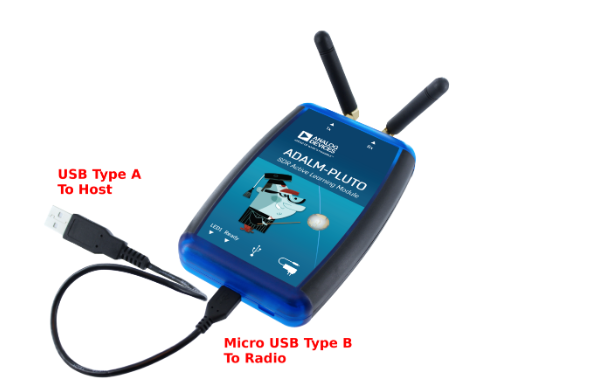

Once the device is connected and the antennas are attached, since, as explained in the introduction, this device will be used together with MATLAB's Communications Toolbox, we need to install this package. To do this, we access to MATLAB Software, press the Ads-Ons explorer, and search the **Communication ToolBox for Analog Devices Adam Pluto**  and then install it. 

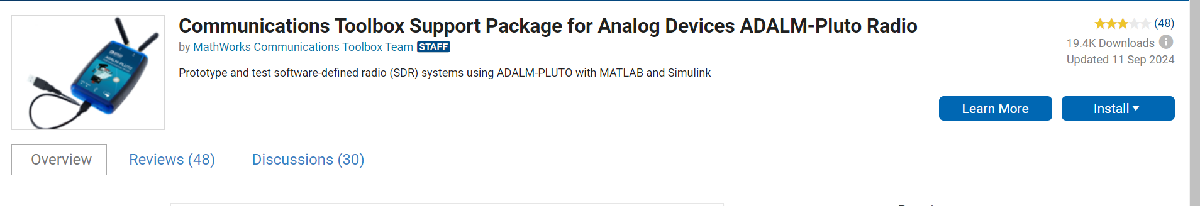

Once we finish, a pop-up window will appear, telling us " **Hardware Support Package requires configuration**", press "Setup Now" and it will ask you to install the USB Driver for the Pluto, follow the instructions. 

Finally, once finished the previous configuration, we just need to **test the connection**, to verify that everything is properly connected:

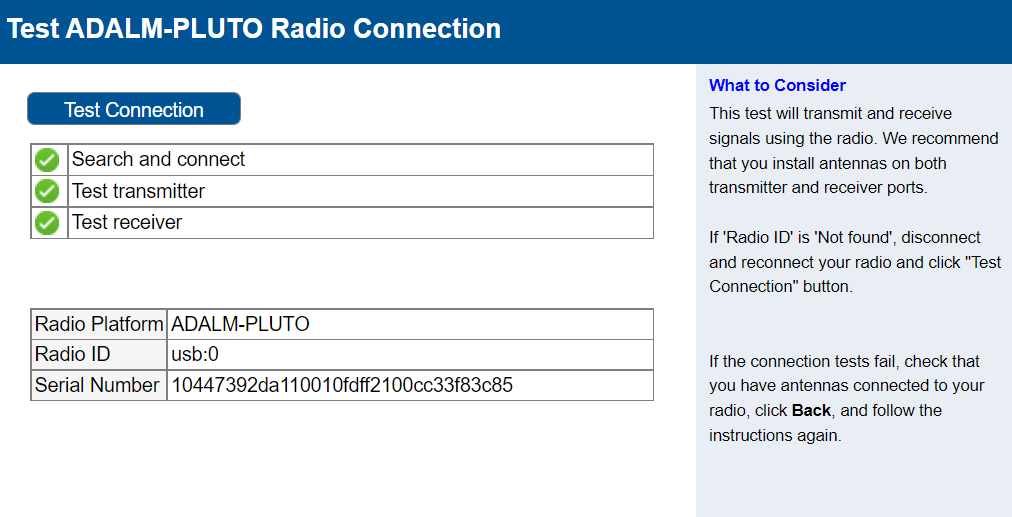

Now let's check the connectivity of the Pluto Radio from the Command Window with the next command: 

findPlutoRadio

ans = struct with fields:
      RadioID: 'usb:0'
    SerialNum: '10447392da110010fdff2100cc33f83c85'


Analyzing the information above, this *find* command provides first the "RadioId", that corresponds to the ID of the Pluto we are going to use, in this case "usb:0". This is specially important, since if we use two different Plutos for transmission and reception, they'll be connected to different computer's ports, and therefore they'll have different "RadioId" to distinguish them. The other field that is shown is the "SerialNumber", that in this case is specific of each Pluto device. 

## 3.Transmission and Reception of a pure tone using only one Pluto SDR (MATLAB).

Once we have set-up our Pluto device properly, we can start using it for transmission and reception. As first example, we are going to generate a pure tone and transmit and recieve it at the same time using just a single ADALM-PLUTO SDR, thanks to its full-duplex capacity.

The first step is to generate this pure tone. In order to do this, we must take into consideration that the SDR needs complex input values, thus the input sinusoid mut have real and imaginary parts. Therefore, we can generate this complex tone following the formula below, where the amplitude,$A\geq0$ , and setting $\theta = \omega t + \phi$, where here $t$ is time in seconds,  $\omega$ is radian frequency, and $\phi$ is a phase offset:


$$s(t) \triangleq A e^{j(\omega t+\phi)}=A \cos (\omega t+\phi)+j A \sin (\omega t+\phi)$$


Now, we can translate this into MATLAB code.

As we have explained before, let's check that our Pluto device is well connected displaying its ID and serial number information:

findPlutoRadio

ans = 1×2 struct array with fields:
    RadioID
    SerialNum


Now, we are going to generate the pure tone. For this, we choose a center frequency of 250 kHz (*fc*), and for meeting the Nyquist criteria, we choose a sample rate of the waveform of 1 MHz (*fs*) . This means that we are going to generate a tone centered in 250 KHz. 

Once we have chosen the frequencies, we have to configure the sinc wave, using the **dsp.SineWave** function in MATLAB, that is a built-in object from the **DSP System Toolbox, **used to generate sine waves or complex sinusoids with configurable properties such as frequency, amplitude, phase offset, and sampling rate. In our case, we are going to specify the central frequency of the tone (*fc=250 kHz*), the amplitude (1), a phase offset of 0, the sample rate "*fs*", the entry "*ComplexOutput*" to 1, meaning that we are generating a complex tone, and the samples per frame. With all these parameters, we generate the tone and save it in the variable "*tone*". 

Finally, in order to see this generated tone, we create a Spectrum Analyzer (*specAn*), enabling its option to find the peak. Since we are generating the tone at 250 KHz, the peak should be found at this frequency.

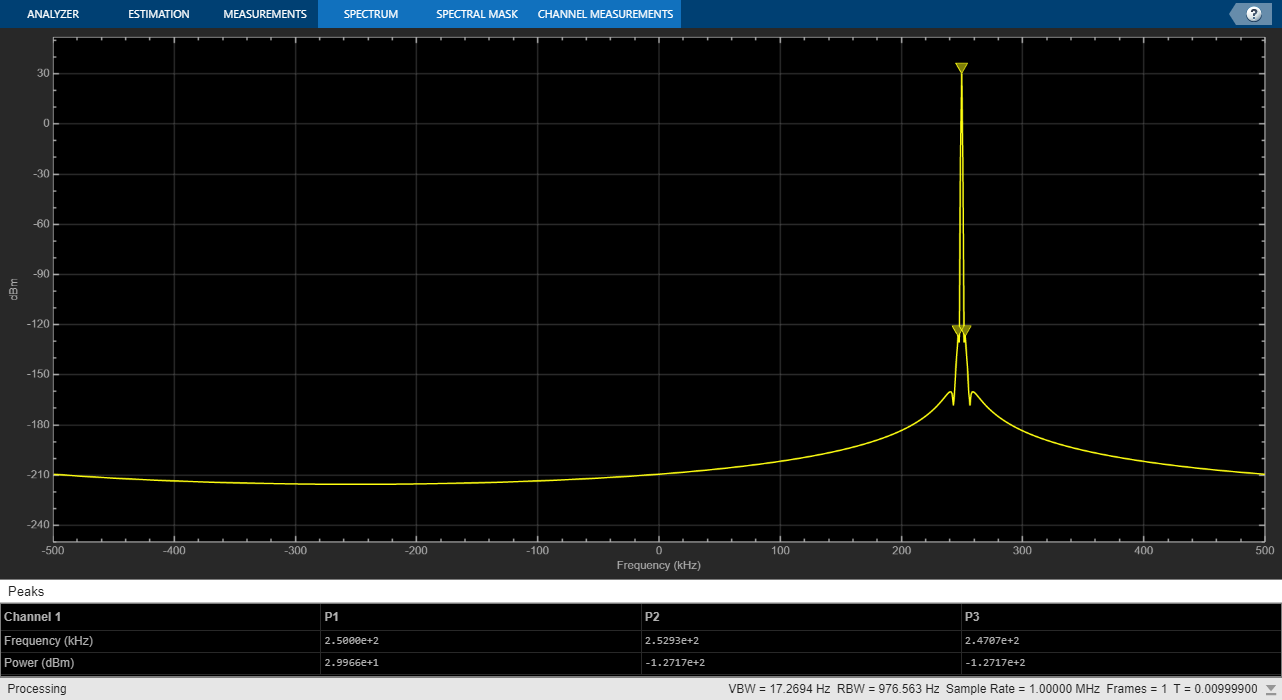

fs = 1e6;   % Sample rate of the waveform in Hz
fc = 250e3; % Tone frequency in Hz

% Sine Wave configuration
sineWaves = dsp.SineWave('Frequency', fc, ...
    'Amplitude', 1, ...
    'PhaseOffset', 0, ...
    'SampleRate', fs , ...
    'ComplexOutput', 1, ...
    'SamplesPerFrame', 0.01*fs);

% Generation
tone = sineWaves();
specAn = spectrumAnalyzer('SampleRate', fs, ...
    'Position',[1 41 1920 963], ...
    'YLimits',[-250 52], ...
    'AxesScaling','Manual');
specAn.PeakFinder.Enable = true;
specAn(tone);

As we can see in the previous image, the tone is perfectly generated at 250 kHz, which is also the position where the peak appears and it is found by the Spectrum Analyzer. Therefore, thanks to this representation, we are already sure that we are correctly generating the corresponding tone that will be sent by the Pluto transmitter antenna. 

We can also check our tone is correctly creted by playing its sound:

fs2 = 4e3;
sound(real(tone), 2*fs2); 

Now that we have everything prepared for the transmission, we just need to configure the transmitter and receiver instantiating the Pluto SDR System Objects with deafult configuration:

tx = sdrtx("Pluto");
rx = sdrrx("Pluto");

Clearly, we can see how we are using the same Pluto for the transmitter and receiver objetcts.

To visualize our complex tone spectrum, we generate like before a new configuration for the Spectrum Analyzer, but in this case we will use it to analyze in real time the spectrum of the signal received by the Pluto:

specAn = spectrumAnalyzer('SampleRate', fs,...
    'SpectralAverages', 40,...
    'YLimits', [0 100],...
    'Title', "Real-time Spectrum Visualization");
specAn.PeakFinder.Enable = true;

## Establishing connection to hardware. This process can take several seconds.


## Establishing connection to hardware. This process can take several seconds.


Finally, we already have set up everything, therefore, we are going to continously Transmit and Receive our complex tone during ${20}^6$ seconds. Exactly we are waiting 5 seconds to start the transmission, once these 5 seconds have gone through (toc>5), we continuously transmit the tone ,* tx(tone)* in the loop, and in the same way, we continuously show in the Spectrum Analyzer the tone received by the pluto,* specAn(rxOut)*, repeating this process for ${20}^6$ seconds. 

tic; %We start counting the time
while toc<20e6
    rxOut = rx();
    specAn(rxOut);
    if toc>5 
        tx(tone);
    end

ans = struct with fields:
      RadioID: 'usb:0'
    SerialNum: '10447392da110010fdff2100cc33f83c85'


end

Once we start running the loop, a new window pop-ups with the Spectrum Analyzer, and after 5 seconds waiting, we see the received tone presented below, which as we were expecting, it's placed exactly at 250 kHz. Therefore, we are properly transmitting and receiving using the same pluto, since we can see how the signal that we have transmitted by the transmission antenna at 250 kHz is received by the receiver antenna and displayed by the Spectrum Analyzer below. Moreover, if we look at the real time Spectrum Analyzer while the code is running, we can see how until 5 seconds have elapsed, we don't see anything in the Analyzer, because the transmission antenna is not transmitting anything. 

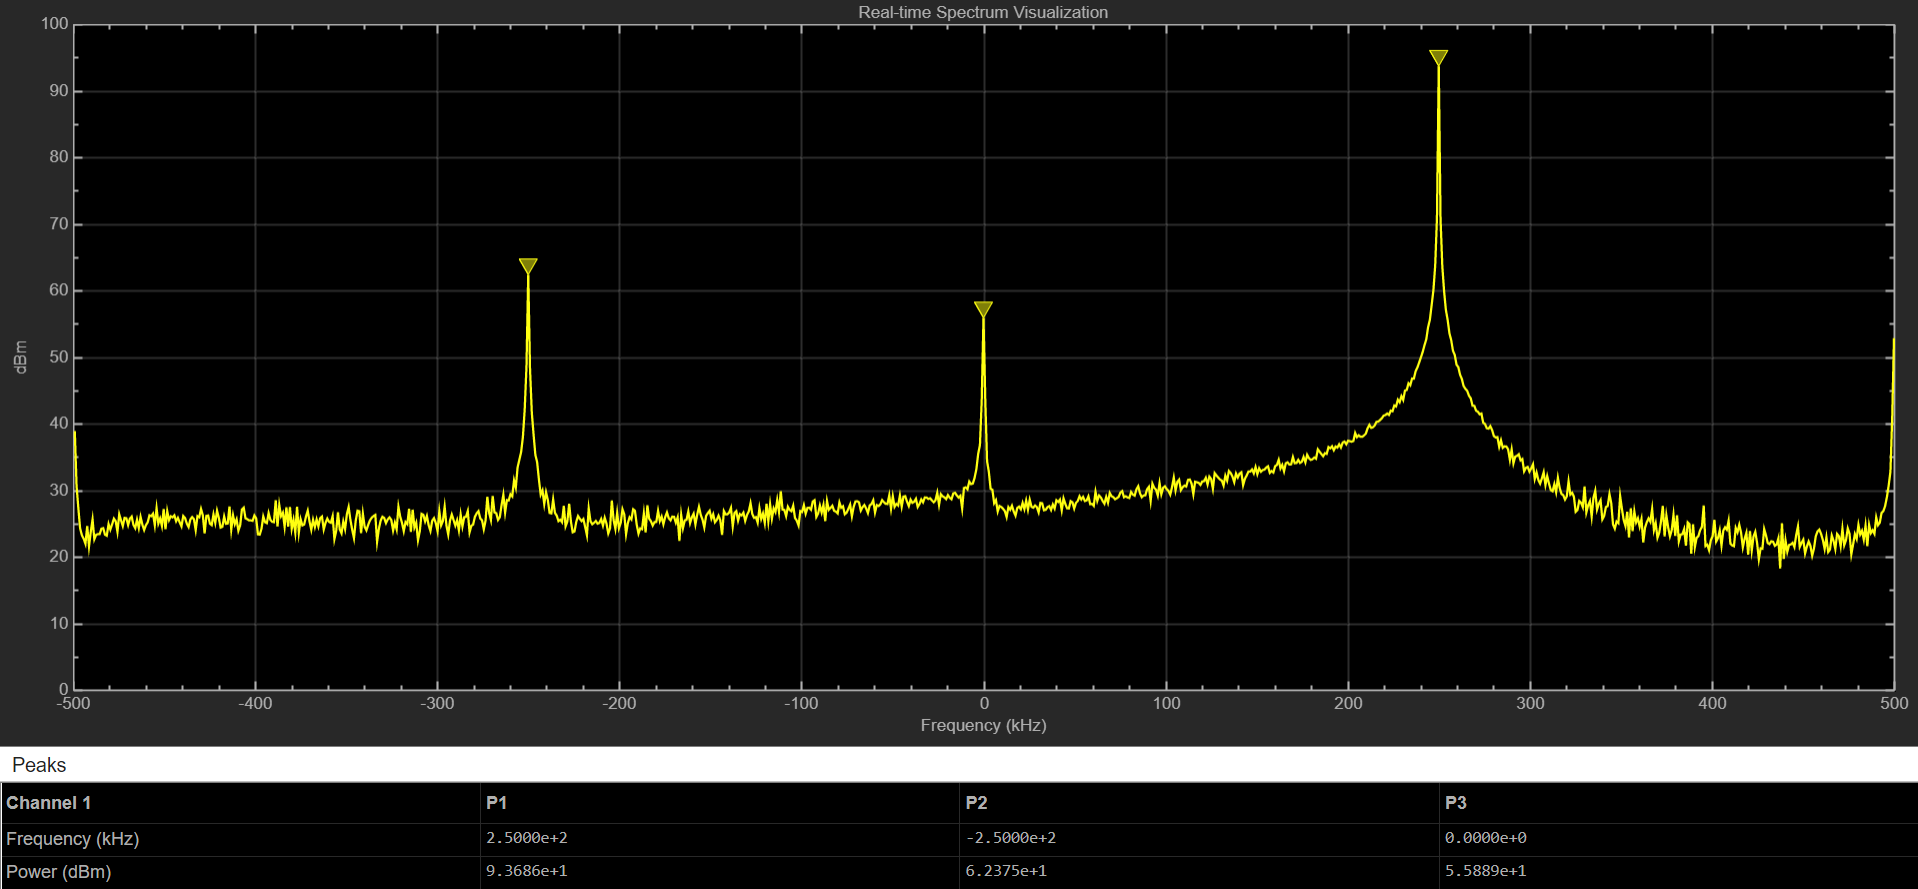

Lastly, since anytime the Pluto SDR is powered on, the transceiver is activated and begins to operate even if the user did not intend to, we need to stop transmitting. For this, we execute the following command:

release(tx);

## 4.Implementation of a QPSK Transmitter and Receiver using Simulink and two Pluto SDR.

To start this second section, we need to open two instances of MATLAB. In one of them, we will launch the transmitter, which will use one of the Pluto devices, and in the other, the receiver, which will use the remaining Pluto device. The first step will be to verify that in both cases we are detecting the two Pluto devices using the **findPlutoRadio()** command shown below. Once this is confirmed, we will implement the transmitter and the receiver using Simulink.

findPlutoRadio

### Transmitter implementation:

The QPSK transmitter is implemented in the Simulink file "**plutoradioQPSKTxSimulink.slx**" located in the folder "**4_QPSK_Simulink**". Its implementation, as we can see in the next picture, consists of several key blocks that work together to generate and transmit a QPSK signal using an **ADALM-PLUTO** device. We can find these three main blocks:

- **Bernoulli Binary Block**: Generates random binary data with a sample time of **2.5 microseconds**, which serves as the input signal. Moreover, as we can see in the scheme, we are generating frames of 11200 samples.

- **QPSK Modulation Block**: Modulates the binary data using QPSK modulation with **Gray coding**, mapping bits to phase changes.

- **Square Root Raised Cosine Filter**:

                    - Upsamples the QPSK signal by a factor of **2**.

                    - Applies pulse shaping using a **Root Raised Cosine (RRC)** filter with the following parameters: 

**                                - Rolloff factor**: 0.5

**                                - Filter span in symbols**: 10

**                                 - Output samples per symbol**: 2

To verify that we are sending properly this signal, we are going to visualize the signal spectrum, adding a **Spectrum Block. **This will allow us to observe and verify the frequency content of the QPSK-modulated signal before transmission.

Finally, once we have everything prepared, we add the **ADALM-PLUTO Transmitter Block**, that transmits the shaped signal at a **center frequency of 915 MHz **setting the **baseband sample rate** to **400 kHz**.

In summary, the binary data is modulated, filtered, and upsampled to prepare it for transmission. The spectrum block lets us see the signal's spectrum to ensure it is correctly shaped and transmitted. Finally, the ADALM-PLUTO transmitter sends the signal wirelessly at the specified center frequency and sampling rate.

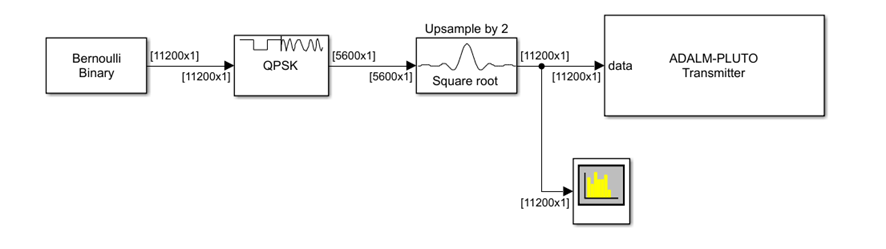

Once we see the implementation, it's important to make some comments about the parameters chosen for scheme. 

Firstly, regarding the transmission frequency of the pluto, 915 MHz, we are using the industrial, scientific, and medical (ISM) bands, which are license-free, this is very important because we can't transmit in any frequency band. 

Secondly, focusing on the parameters of the filter, we are using a rolloff factor of **0.5, **which is a moderate choice, since this value achieves a  balance between spectral efficiency (narrow bandwidth) and avoiding intersymbol interference (ISI), having in mind that smaller rolloff factors (e.g., 0.2 or 0.3) result in narrower bandwidth but require a sharper filter, which can be more computationally intensive, while higher values of rollof factors consume more bandwidth, which is a limited resource. A span of **10 symbols** is sufficient to capture the majority of the filter's energy. On the other hand, an upsampling factor of **2** is typical for pulse shaping in QPSK systems. This provides a trade-off between resolution and computational load (obviously higher values of this factor could improve performance, but also increase the sampling rate and resource usage).

From the previous implementation, thanks to the analyzer, we get the following spectrum, that corresponds to the** signal we are transmitting **with the first Pluto:

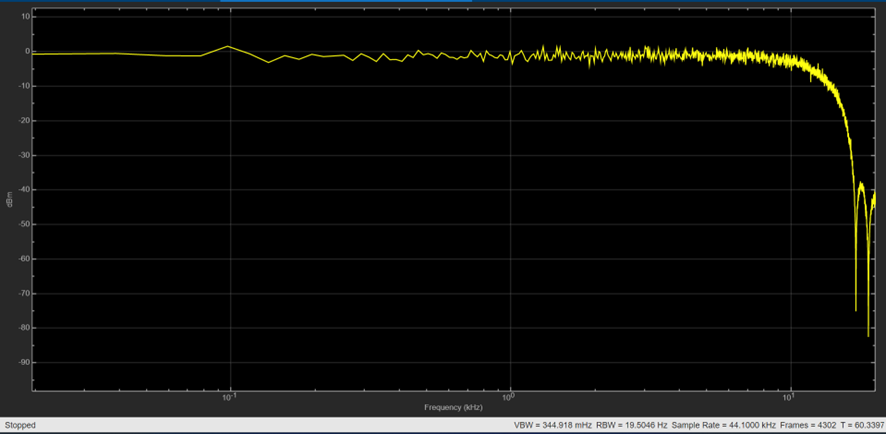

Based on the transmitted spectrum shown in the previous image, we can get some insights. Firstly, we clearly have a flat frequency response in the passband, since the spectrum appears relatively flat over the central portion, which is expected for a properly modulated **QPSK signal** with pulse shaping.This indicates that the transmitter is working correctly in generating the desired signal without major distortions or excessive attenuation. Moreover, the spectrum starts to roll off smoothly around the edges, which aligns with the **Root Raised Cosine filter** used in the design. In fact, the smooth roll-off is a direct result of the **0.5 rolloff factor**, which adds a moderate transition band to control bandwidth usage.This roll-off behavior confirms that the filter is functioning as intended.

Regarding the **Signal Bandwidth, **the spectrum spans a frequency range consistent with the expected bandwidth for a **QPSK signal** after pulse shaping. If we remember the previous analysis, we had a symbol rate of **400 kbps** (parameter samples per frame) and a rolloff factor of **0.5 **in the cosine filter, the theoretical bandwidth is: $B=\textrm{Symbol}\;\textrm{rate}\times \left(1+\textrm{Rollof}\;\textrm{Factor}\right)=400\;\textrm{kHz}\times 1\ldotp 5=600\;\textrm{KHz}\ldotp$ And, if we look at the spectrum, it appears to occupy approximately this bandwidth, confirming that the system parameters align correctly.

The noise appers to be low, and the spectrum shows minimal out-of-band emissions.This indicates that the transmitter and filter are suppressing unwanted spectral components effectively.

Finally, the **sharp drop-off **beyond the signal bandwidth suggests that the filter span and upsampling are working correctly to limit out-of-band energy.

Once we are sure that the transmitter implementation is correct, we can continue with the receiver.

**Receiver implementation:**

This implementation, made in the Simulink file "**plutoradioQPSKRxSimulink.slx**" corresponds to the following scheme, where the receiver processes signals from the transmitter and synchronizes them to recover the transmitted data. We are going to specify the proper parameters to ensure that the receiver correctly demodulates the signal. 

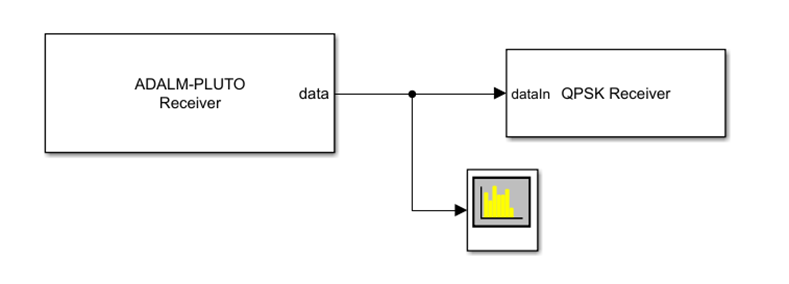

As we can see, we are adding a spectrum analyzer block to verify that we are properly receiving the transmitted signal.  For getting this spectrum, we first  run the simulation of both transmitter and receiver infinitely.This allows us to observe the spectrum of the received signal, as spectrum analysis requires continuous input to compute the power spectral density. Thanks to this, we get the following spectrums presented below, both of them are captured at the same point (spectrum analyzer), but in different time instants, obviously they have slightly differences, however, both of them are pretty similar to the original one transmitted, although with a bit more noise, specially in the guardbands. 

Regarding the bandpass, we see how now it isn't as flat as before, because again, we have some noise here. 

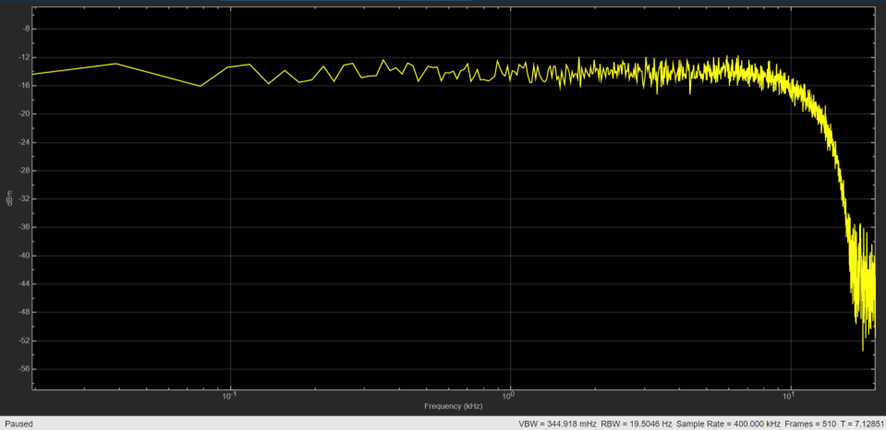

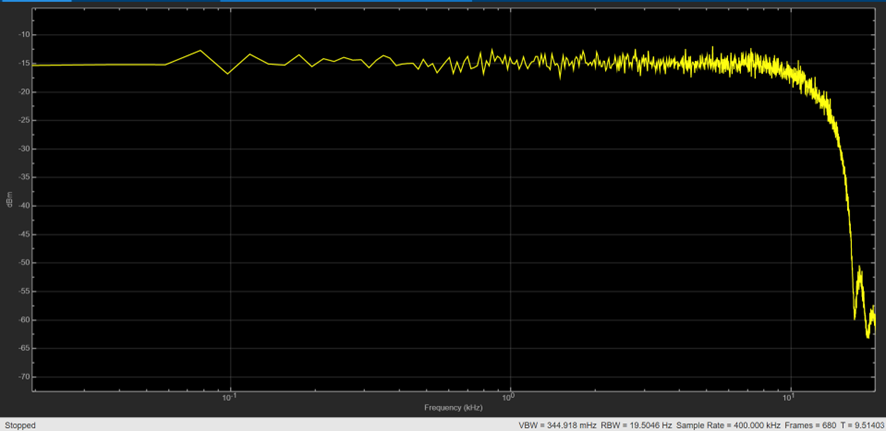

Once we know the received spectrum is correct, we want to obtain the constellation after the receiver, to verify that we are properly demodulating and getting a QPSK. 

For doing this, we are going to run a **finite time simulation**, exactly we are going to run the **transmitter for 5 seconds** and the **receiver for 0.1 seconds**.The reason for this is that the **constellation diagram** block in Simulink cannot efficiently process real-time infinite signals, therefore: 

- By running the transmitter longer, we ensure enough signal data is generated.

- Running the receiver for only 0.1 seconds allows the constellation diagram to capture the output after the carrier synchronizer and display the symbol points clearly.

Before seeing the generated constellation, let's break down step by step each block of the receiver and its role. In the next picture, we can see what we have inside the "QPSK Receiver" block shown in previous scheme: 

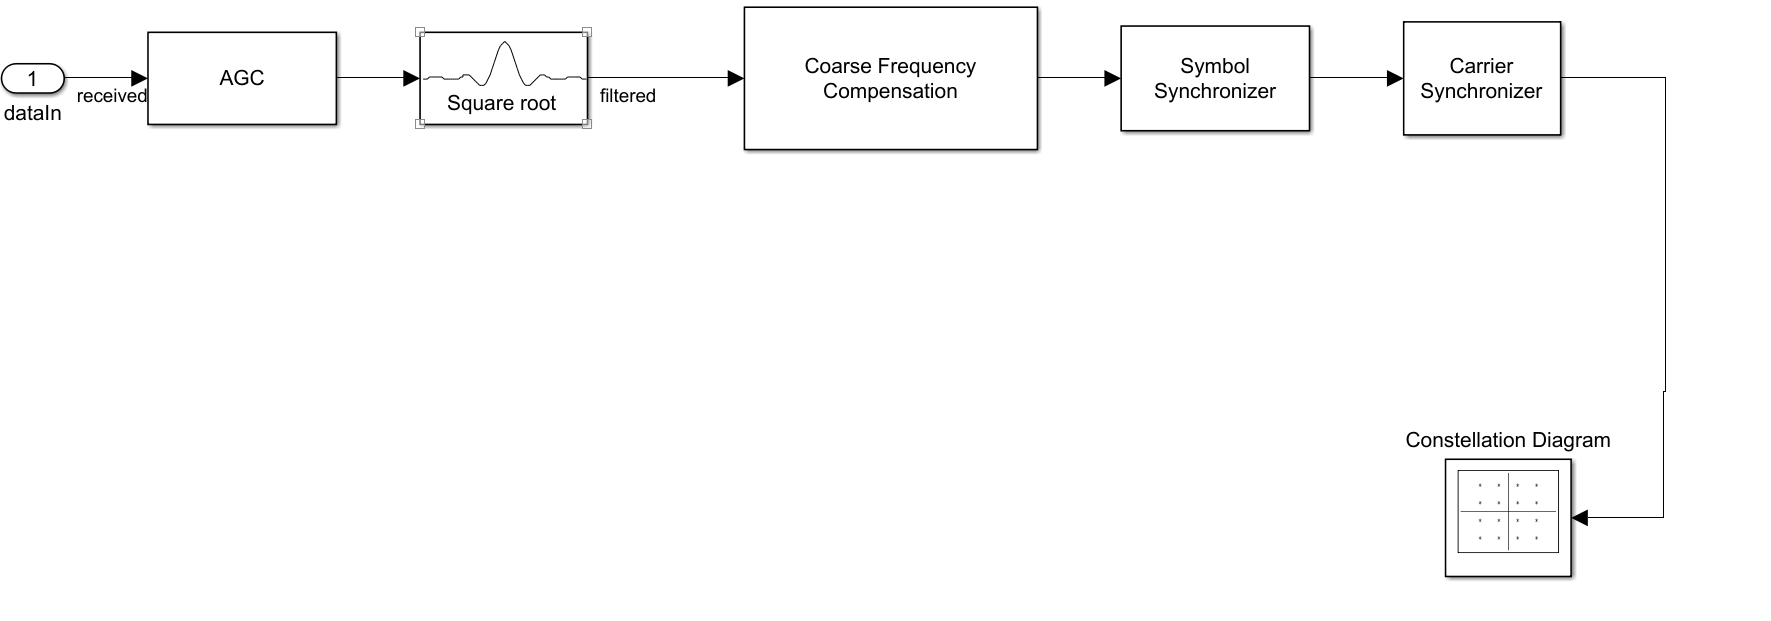

**1. ****Automatic Gain Control (AGC):** adjusts the signal power level to a desired value automatically. This  AGC ensures the received signal power is appropriate for the downstream blocks, preventing saturation or under-utilization of subsequent filters. The parameters chosen for this block are: 

- **Step size for gain updates**: 0.01 (determines how quickly the gain adjusts).

- **Target output power level**: 2 (ensures the output maintains an average power level of 2).

- **Length of averaging window**: 50 (smooths out the power measurements to avoid abrupt changes).

- **Maximum power gain**: 60 (limits the maximum gain to avoid excessive amplification).

**2. ****Square Root Raised Cosine (RRC) Filter: **this is a matched filter that reduces intersymbol interference (ISI) caused by the channel. The RRC filter works as a pulse shaping filter, and when matched with the transmitter filter, it optimizes signal recovery. As parameters we choose: 

- **Roll-off factor**: 0.5 (It controls the bandwidth of the filter. A roll-off of 0.5 provides a good trade-off between bandwidth efficiency and ISI reduction).

- **Filter span in symbols**: 10 (specifies the length of the filter in symbol durations).

- **Input samples per symbol**: 2 (the signal is oversampled, providing better resolution for synchronization).

**3. ****Coarse Frequency Compensation: **this block corrects large frequency offsets introduced by the channel or hardware mismatch. Frequency offsets can cause severe distortions to the signal. This block ensures the frequency is roughly aligned before further synchronization.

**4. Symbol Synchronizer: **it adjusts the sampling time to align with the symbol boundaries, ensuring the symbols are recovered correctly. We choose as parameters:

- **Phase detector gain**: 5.4 (determines the sensitivity of the phase detector, which helps detect timing errors).

- **Normalized bandwidth of the loop filter**: 0.01 ( controls the bandwidth of the timing recovery loop, ensuring smooth convergence).

.**5. ****Carrier Synchronizer: **this block compensates for residual carrier frequency and phase errors to align the carrier signal with the receiver. The parameters chosen are: 

- **Samples per symbol**: 2 (the input is oversampled at 2 samples per symbol).

- **Loop sampling factor**: 1 (specifies the factor at which the loop operates).

- **Normalized bandwidth**: 0.01 (ensures smooth phase and frequency corrections).

Without carrier synchronization, phase and frequency errors can distort the constellation diagram, leading to symbol errors.

Now, if we use the two MATLAB instances to run both the Simulink trasmitter and receiver, with the two ADALM-Plutos, we get the constellation shown below, where we are clearly recovering a QPSK constellation. This helps us verify that our Simulink implementations of the QPSK transmitter and receiver are correct.

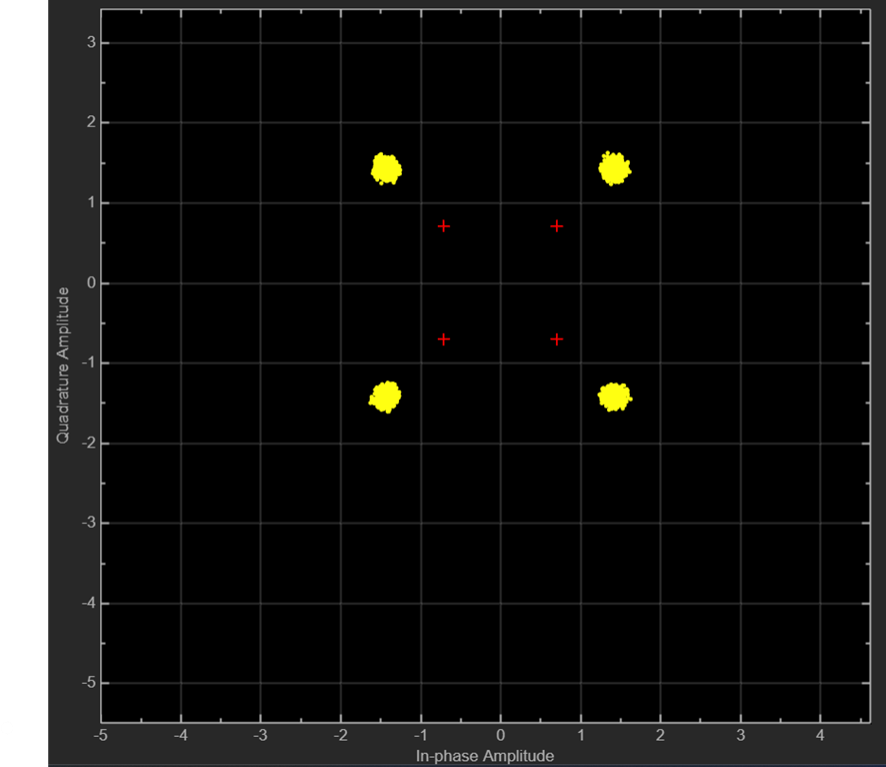

## 5. Implementation of an OFDM Transmitter and Receiver using Simulink

Since we have already successfully implemented a **QPSK communication system** using Simulink, we now move on to a more complex system: the **OFDM (Orthogonal Frequency Division Multiplexing) system**.

This implementation follows the scheme outlined below, where different Simulink blocks are used for the transmission and reception chains.

**Transmission Chain**

The transmission side consists of three main blocks:

**        1. Bernoulli Binary Generator**:

- Generates random bits for transmission.

- Configured with a **sample time of 1 microsecond** and **106 samples per frame**.

**        2. QPSK Modulator**:

- Maps the generated bits onto a **Gray-coded QPSK constellation**.

- Uses a **phase offset of π/4** to properly align the constellation points.

**        3. OFDM Modulator**:

- Converts the QPSK symbols into an OFDM signal.

- Configured with an **FFT length of 64** and a **cyclic prefix length of 16**.

The resulting OFDM signal is then passed through an **AWGN (Additive White Gaussian Noise) channel** with a **Signal-to-Noise Ratio (SNR) of 20 dB**. Reducing the SNR will naturally lead to a noisier received signal, impacting the system's performance.

**Reception Chain**

At the receiver, the process is simplified:

- An **OFDM Demodulator** block is used to recover the transmitted data.

- The demodulator must be configured with the **same parameters** (FFT length and cyclic prefix length) as used in the modulator to correctly interpret the incoming signal.

This setup allows us to observe the behavior of an OFDM system under noise conditions and gain practical insights into the robustness and performance of multicarrier communication systems. The complete block diagram is presented below: 

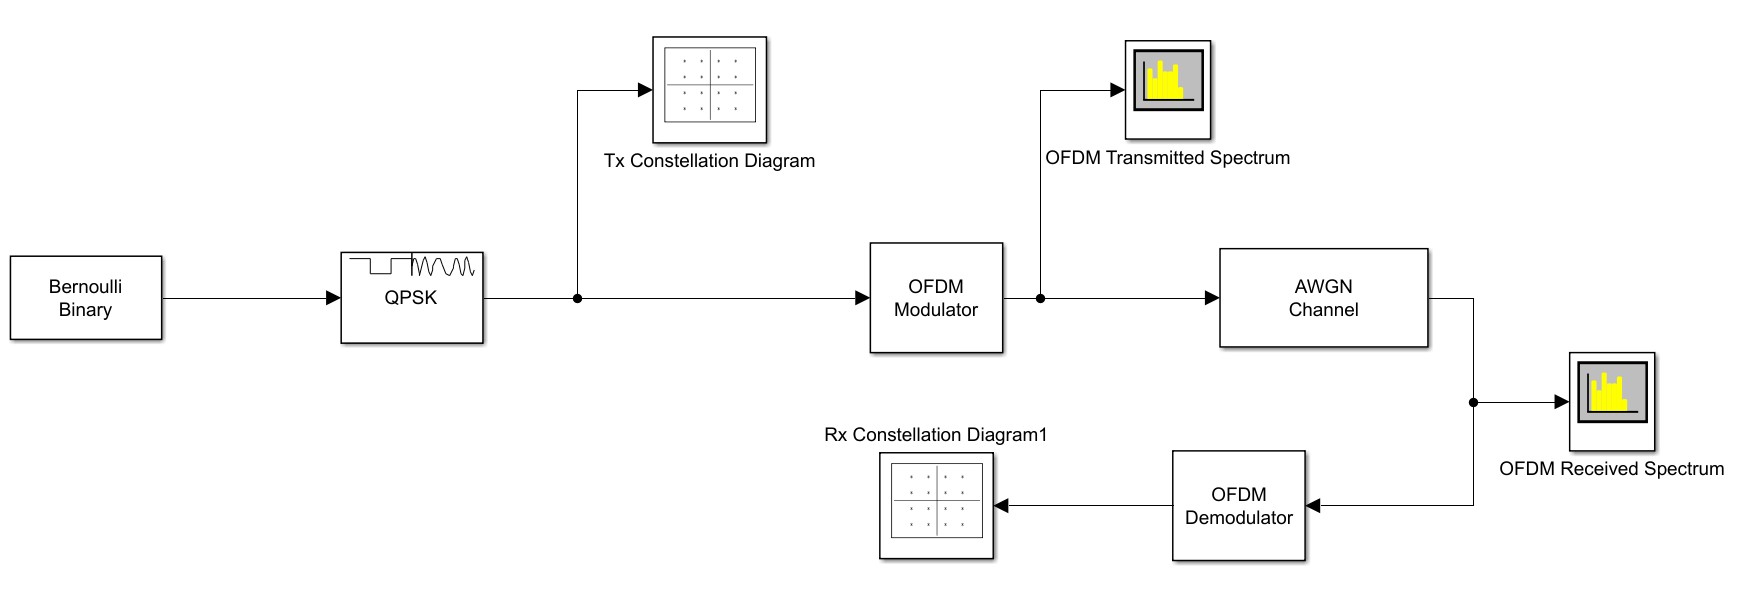

In order to verify the correctness of the system, we start representing the constellation diagram of the transmitted signal. Since we are generating a perfect QPSK signal, the constellation below has a perfect shape. In fact, if we zoom in into the red crosses, we can see the yellow dots correponding to the information we have sent. 

## 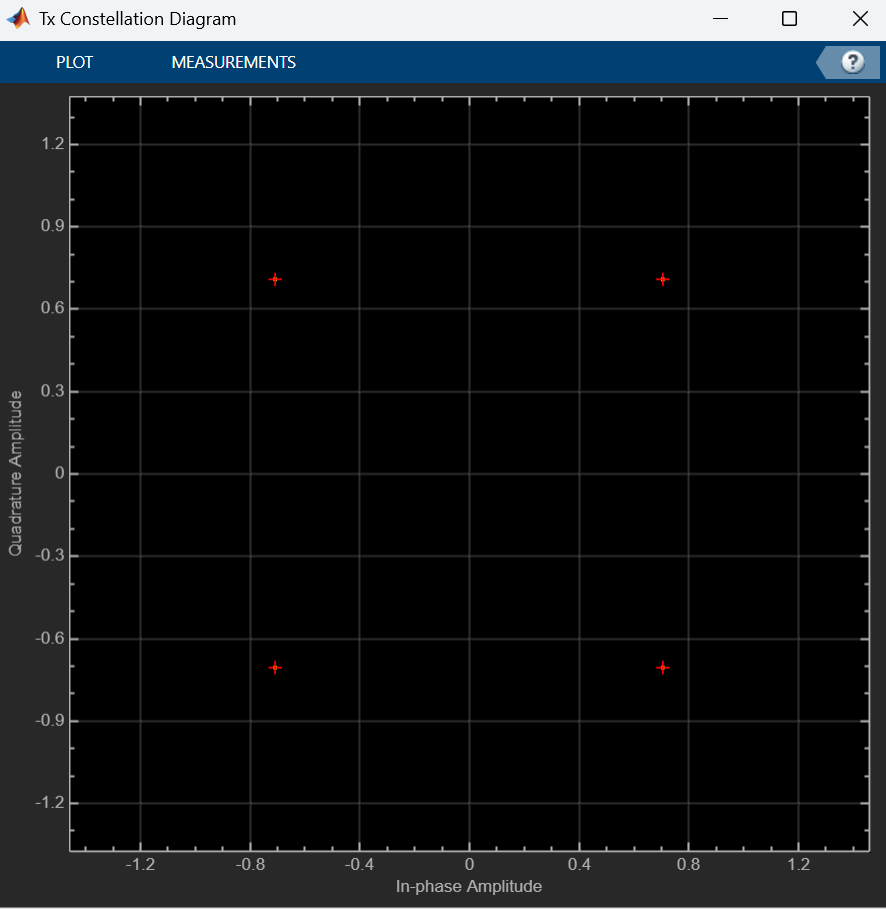

Now, if we look at the transmitted OFDM spectrum captured by the analyzer, we see the common OFDM spectrum that we were expeting. This means that the transmission chain is properly working.  

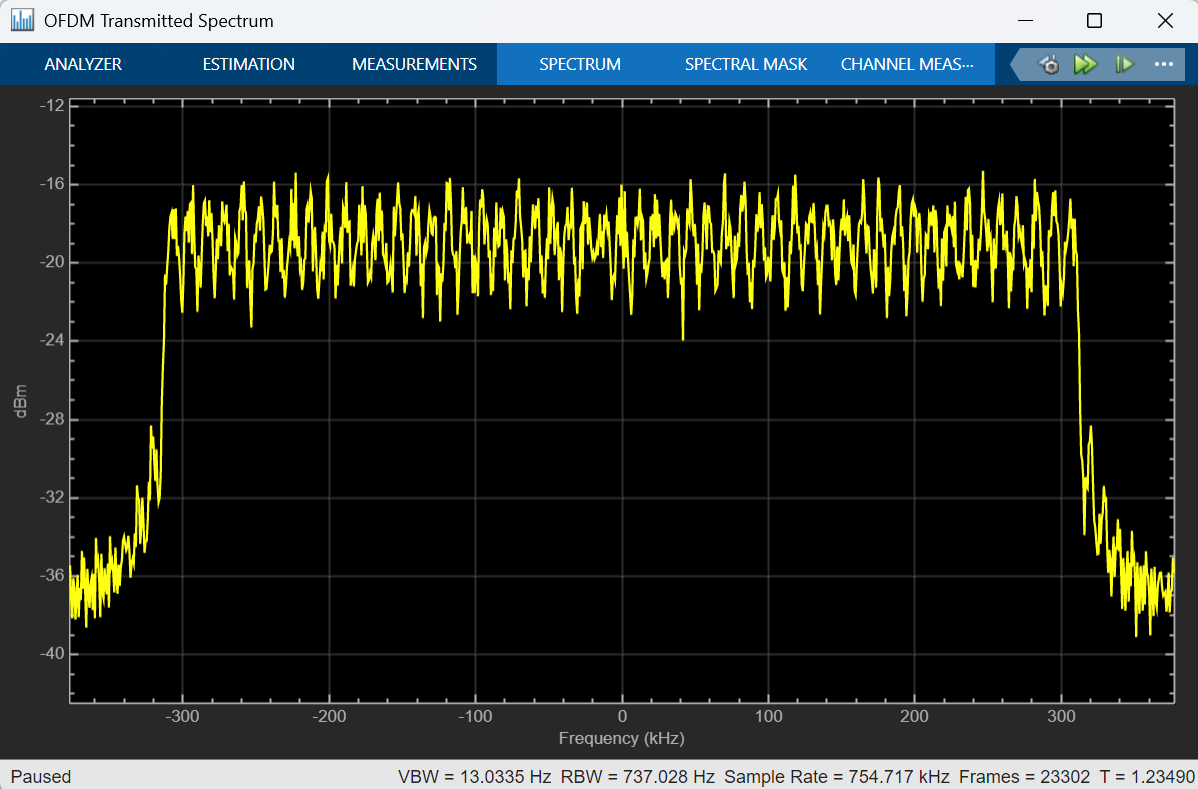

The next step, as previously explained consists of sending the signal through the AWGN channel. Then, the spectrum of the contaminated received OFDM signal is presented by the following analyzer. As we can see, the shape is similar to the one of the transmitted signal spectrum, but distorted by noise and channel effects.

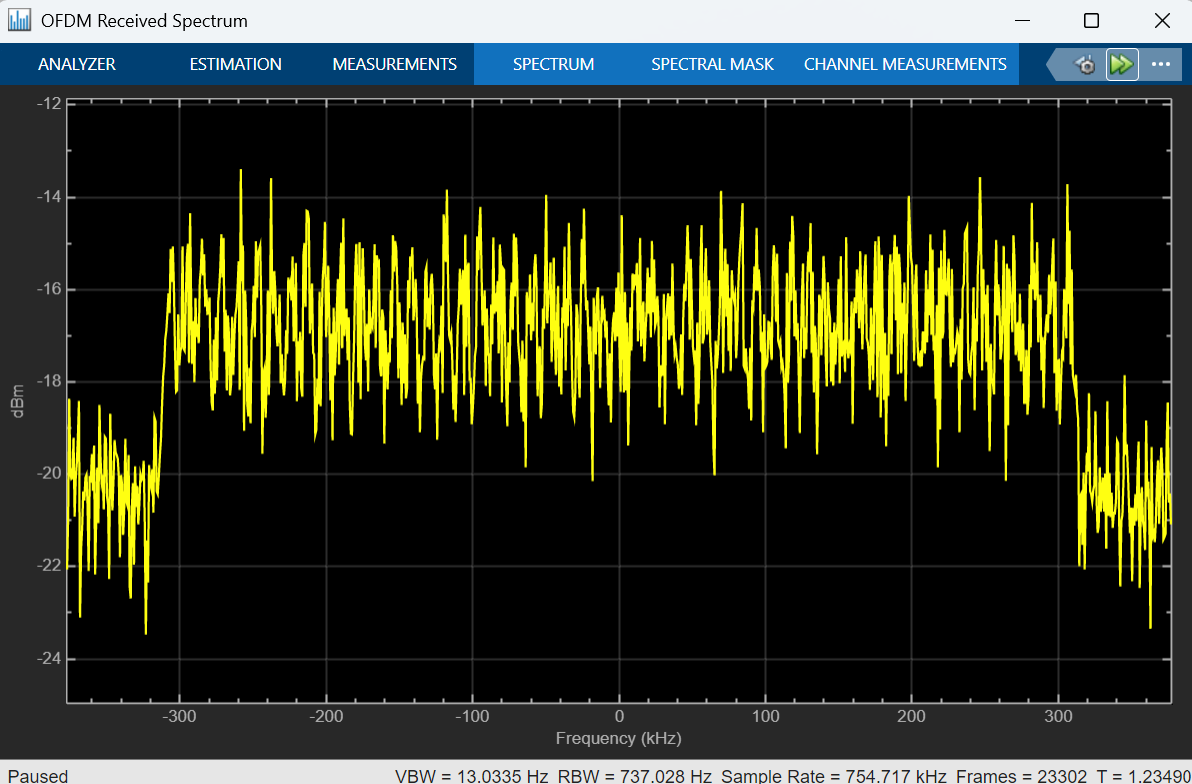

Finally, once we know that the transmission chain is correct, we obtain the constellation after the OFDM Demodulator block. As it is presented below, we clearly have a QPSK constellation, however, more noisy than the original one, due to the noise and channel effects. Despite this, it is clear that the OFDM system implemented with Simulink is perfectly performing its labor, as we were expecting. 

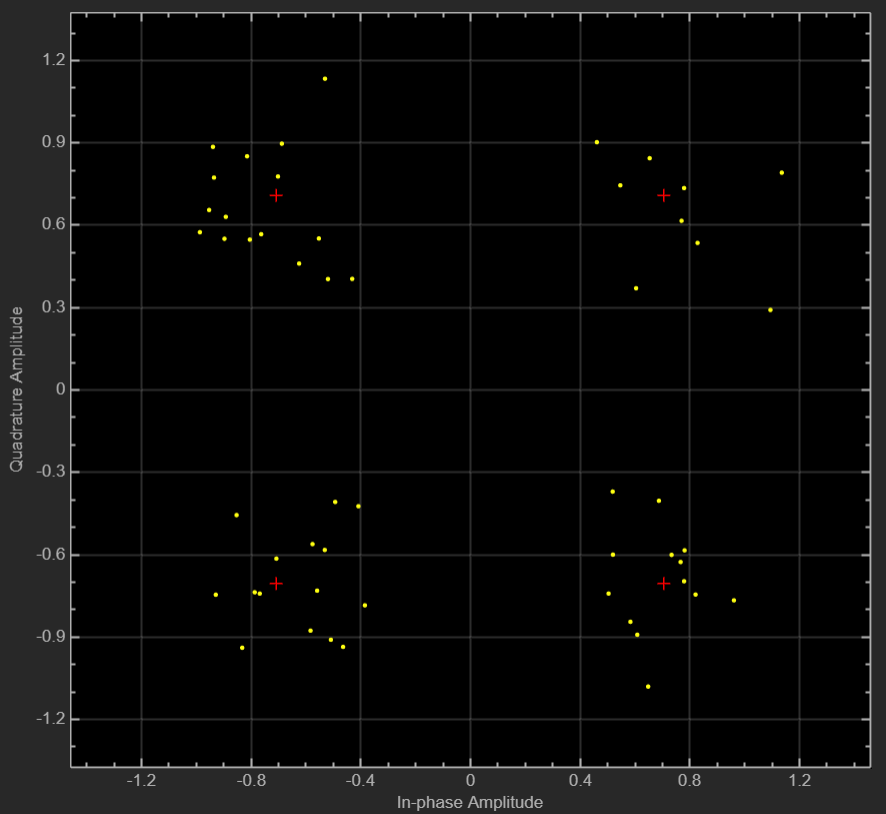

### 5.2 OFDM Transmission and Reception with two Plutos

In this section, we adapt the previously implemented OFDM system to transmit the generated signal over a real wireless channel using two ADALM-Pluto SDRs, one for transmission and another for reception. To achieve this, we replace the AWGN channel module used earlier, with the actual transmission and reception blocks corresponding to the Pluto devices. These blocks are configured using the same parameters previously employed for QPSK modulation, ensuring consistency across both simulations and real-world experiments. The final block diagrams illustrating the updated system configuration are presented below.

#### OFDM Transmitter

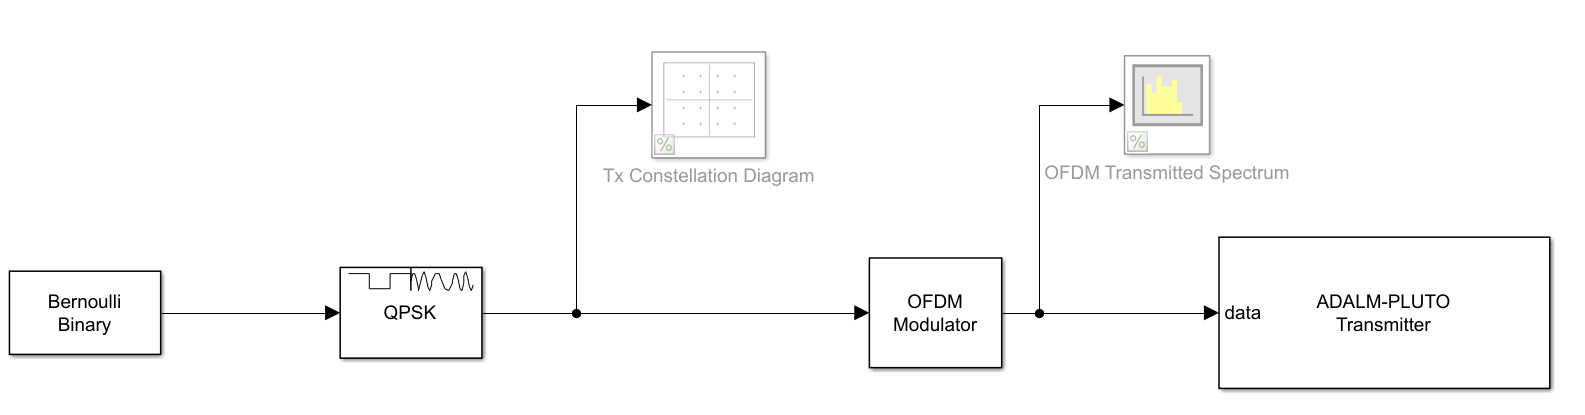

#### OFDM Receiver

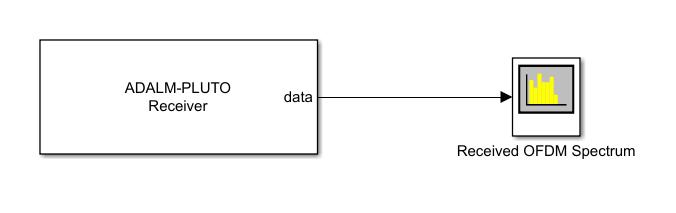

By examining the received spectrum shown in the figure below, it is evident that we are successfully receiving the expected OFDM signal. The characteristic shape of the OFDM spectrum is clearly visible, confirming that the transmission and reception through the Pluto SDRs are functioning as intended. However, we also observe the presence of noise and various distortions introduced by the real channel, which are typical in practical wireless environments. 

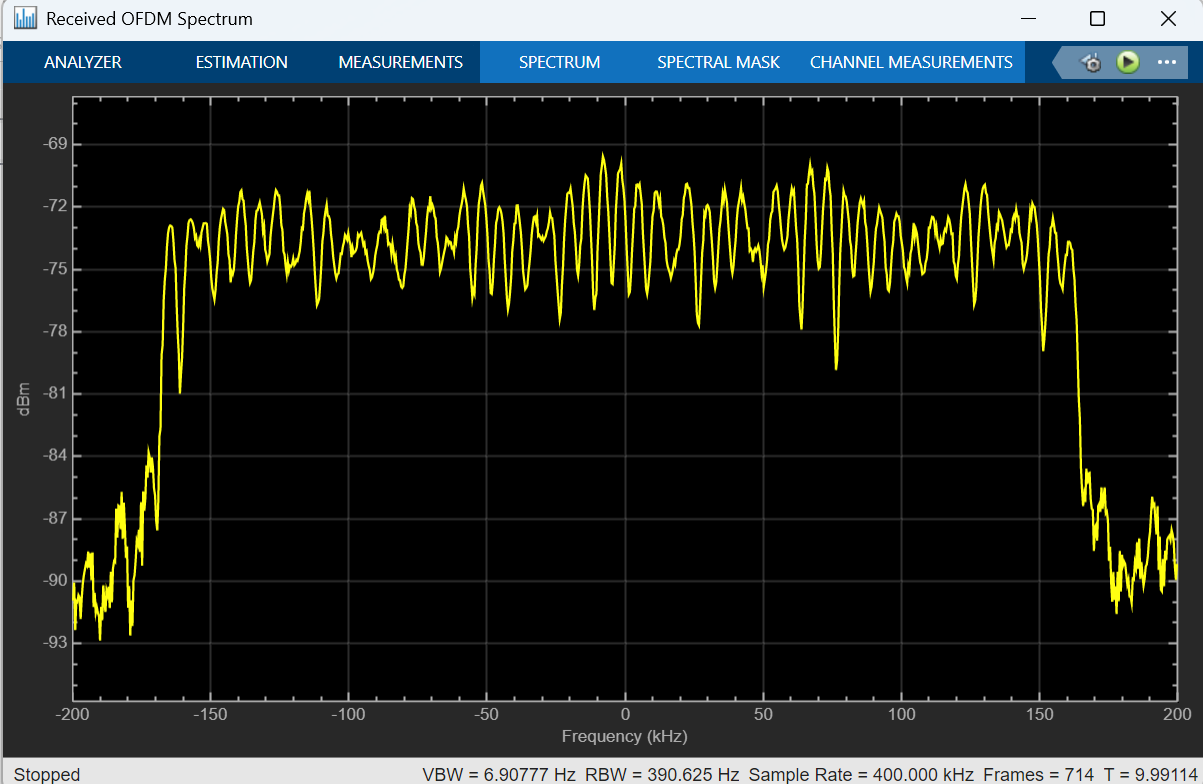

## 6. Implementation of a BPSK Transmitter and Receiver using MATLAB and two Pluto SDR.

Once a QPSK transmitter and receiver have been successfully implemented using Simulink, by configuring parameters of black boxes, we will proceed to a more detailed implementation using MATLAB, programming each line of code instead of using Simulink modules. However, in this case, we will implement it for a BPSK modulation.

The steps will be as follows, using the files within the folder **6_BPSK_Matlab**. 

First, we** generate the message** we want to send, in this case, the BPSK IQ samples, using the file "***BPSK_Message_Generator.mlx***`"`. This script will generate the frames to be transmitted and save them in the file "*BPSK_IQ_samples_simulation.mat"*.

Once we have the data we want to transmit, we use the file "**BPSK_Transmitter.mlx"** to transmit the IQ samples using an ADALM-Pluto device. Here, we simply load the previously generated samples stored in "*BPSK_IQ_samples_simulation.mat"* and configure the Pluto device to transmit them indefinitely.

Now, we need to **receive these samples**. For this, we use the final file, "**BPSK_Receiver.mlx**", which contains both the configuration of the receiving ADALM-Pluto device and the processing of those samples. Moreover, in this case, we are going to analyze both, the spectrum of the received signal, and the demodulation of the signal, doing the proper frequency and phase corrections and seeing its final constellation, veryfing that it is the original BSPK constellation we had sent.

To successfully execute the transmission, we must use one instance of MATLAB running the transmitter program, "*BPSK_Transmitter.mlx"*, with the first ADALM-Pluto device. Simultaneously, we must use another MATLAB instance to run the receiver program, "*BPSK_Receiver.mlx*`"`, with a second ADALM-Pluto device.

Finally, if we examine each of the individual *.mlx* files, we can find a more detailed explanation of each process.

## 7. Implementation of an OFDM Transmitter and Receiver using MATLAB and two Pluto SDR

Finally, once we have verified in the previous section that we are capable of completing the full process of transmitting and receiving (including demodulating the message) a BPSK signal using two ADALM-Pluto devices, we will proceed to implement a more complex setup involving an OFDM signal, using the files contained in the folder "**7_OFDM_Matlab**".

In this case, the transmission will again be performed using a MATLAB instance running the scripts **"OFDM_Message_generator.mlx"** and "**OFDM_Transmitter.mlx**`"`, which generate the OFDM signal and configure the first Pluto device for transmission, respectively. Meanwhile, the reception will be carried out using another MATLAB instance running the script "**OFDM_Receiver.mlx**`"` with the second Pluto device.

Since OFDM signals are more complex, instead of performing the synchronization and frequency correction processes, we will simply analyze the spectrum to verify that the transmission process is working correctly, ensuring that the second Pluto device receives the expected signal.